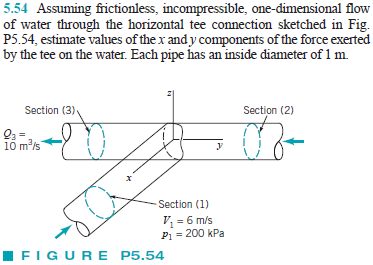

# constants

u = symunit;
rho = 999*u.kg/u.m^3;

# inflow properties

% -----------------------
% section 1
p1 = 200*u.kPa;
V1 = 6*u.m/u.s;
D1 = 1*u.m;
A1 = sympi*D1^2/4;
mdot1 = rho*A1*V1;
% -----------------------
% section 2
syms V2;
A2 = A1;
mdot2(V2) = rho*A2*V2;
% -----------------------

# outflow properties

% -----------------------
% section 3
syms V3;
A3 = A1;
Q3 = 10*u.m^3/u.s;
mdot3(V3) = rho*A3*V3;
% -----------------------

# conservation of mass

eqn = sym.zeros(4,1);
eqn(1) = mdot3 == rho*Q3;
eqn(2) = formula(mdot1)+formula(mdot2) == formula(mdot3);

# Bernouli's Equation

syms p2 p3;
eqn(3) = p1+1/2*rho*V1^2 == p2+1/2*rho*V2^2;
eqn(4) = p1+1/2*rho*V1^2 == p3+1/2*rho*V3^2;

# conservation of momentum (x-direction)

syms Fx;
eqn(5) = Fx-p1*A1 == -mdot1*(-V1);

# conservation of momentum (y-direction)

syms Fy;
eqn(6) = Fy-p2*A2+p3*A3 == -formula(mdot2)*(-V2)+formula(mdot3)*(-V3);

# solution

[Fx Fy p2 p3 V2 V3] = solve(eqn, [Fx Fy p2 p3 V2 V3]); %#ok
Fx = rewrite(simplify(Fx), u.kN);
Fx_vpa = vpa(Fx, 5) %#ok

$$Fx\_vpa = 185.33\,\mathrm{kN}$$

Fy = rewrite(simplify(Fy), u.kN);
Fy_vpa = vpa(Fy, 4) %#ok

$$Fy\_vpa = -45.82\,\mathrm{kN}$$

p2 = rewrite(simplify(p2), u.kPa);
p2_vpa = vpa(p2, 5) %#ok

$$p2\_vpa = 195.34\,\mathrm{kPa}$$

p3 = rewrite(simplify(p3), u.kPa);
p3_vpa = vpa(p3, 5) %#ok

$$p3\_vpa = 137.01\,\mathrm{kPa}$$

V2_vpa = vpa(V2, 3) %#ok

$$V2\_vpa = 6.73\,\frac{m}{s}$$

V3_vpa = vpa(V3, 4) %#ok

$$V3\_vpa = 12.73\,\frac{m}{s}$$

clear Fx_vpa Fy_vpa p2_vpa p3_vpa V2_vpa V3_vpa;